% Specify the folder containing your images
image_folder = 'C:\Users\shukl\Documents\GitHub\DogBreed\train\Dog';

% Get a list of all image files in the folder
image_files = dir(fullfile(image_folder, '*.jpg'));

% Initialize a matrix to store vectorized images
image_matrix = zeros(784, length(image_files));
org_img=[]


org_img =

     []




% Loop through each image file in the folder
for i = 1:length(image_files)
    % Read the current image
    original_img = imread(fullfile(image_folder, image_files(i).name));

    % Convert the image to grayscale
    gray_img = rgb2gray(original_img);

    % Resize the image to 28x28
    resized_img = imresize(gray_img, [28, 28]);

    % Convert the resized image to a vector and store it as a column in the matrix
    image_vector = double(resized_img(:));
    image_matrix(:, i) = image_vector;
    org_img(:,i) = double(original_img(:));

end

% Display the size of the image matrix
disp(['Size of Image Matrix: ', num2str(size(image_matrix))]);

Size of Image Matrix: 784  399


    File=image_matrix'

File =    255   255   255   255   255   255   254   255   255   254   254   254   254   254   255   255   255   255   255   255   255   255   240   218   209   193   233   245   255   255   255   255   255   255   255   252   242   255   255   253   254   254   255   255   255   255   255   255   255   253
   255   255   255   255   255   254   254   255   254   254   255   255   255   254   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   254   255   251   243   248   253   254   253   254   254   254   255   255   255   255   255   255   254
   117   115   124   110   117   120   113   113    73    35    18    42   121   121   123   115   109   119   111    87    94    74    74    90    89    76    66    73   118   112   129   108   116   114    71    40    31    25    20    28   114   123   121   120   111   114   106   105    85    83
   156   112   114   209   120    62    67    64    63    96   145   148   161   149   128

    org_file= org_img

org_file =    255   255   118    91   112   109   142   110   136   113    16   177   125   253   255   138   253   255   255   255    21   143   105   187   211   253    57    27   144    65    75    72   109   123   142    98   131    74   105   255   125   120    61    64    50   163    98    13   160   182
   255   255   109    64   117   112   136   111   146   115    14   177   127   251   255   140   253   255   255   255    22   154   107   187   211   253    59    27   132    65    74    74   110   130   140    96   126    74   106   255   126   121    62    62    47   164   101    13   155   183
   255   255   118    56   118   102   133   112   153   118    15   177   129   248   255   145   253   255   255   255    22   166   111   187   211   253    58    27   133    67    74    71   112   138   143    94   113    75   107   255   121   111    63    58    44   162    96    13   156   186
   255   255   119    70   122   101   139   113   159   120    23   178   131   249  


        T_class1=File.'

T_class1 =    255   255   117   156    92    99   128   126   154   114    42   180   102   249   255   154   251   255   255   255    28   178   108   191   213   253    62    26   132    79    97    67   126   130   124   127   120    96   120   255   104    93    84    40    60   166    87    68   135   175
   255   255   115   112   137    90   137   136   162   117   139   178   114   247   255   151   251   255   255   255    29   136   109   194   215   254    38    29   124    68    97    73   135   144   119   125   119   101   123   255    71    96    79    36    60   160    91    68   124   178
   255   255   124   114   145    71   114   135   135   112   170   178   125   222   255   145   250   255   255   255    29   123    79   197   232   254    38    40   121   106   102   124   134   142   119   124   109   101   127   255    57   105    79    43    64   160    97    67   135   176
   255   255   110   209   129    91   109   132   128   112   178   182   121   198  


        ranks=[1,2,3,6,7,8,9,10];

        error_class1 = nan(size(ranks));
        numclass1=size(T_class1,2)

numclass1 = 399

        Dist_mat_class1_array_asc=nan(length(ranks),numclass1);
        threshold_rank_1=nan(size(ranks));
        elbow_indx_rank_1=nan(size(ranks));

        for i = ranks
            %fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\Mnist\

            T_class1_temp=T_class1;
            Dist_mat_class1=[];


            BF_class1=l1pca_BF(T_class1,i,1,20,20,'')
            for k = 1 : numclass1
                A=T_class1(:,k);
                Dist_mat_class1(k)=norm((A-(BF_class1*BF_class1.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_class1,[],"all");
            max_val=max(Dist_mat_class1,[],"all");
            Dist_mat_class1= Dist_mat_class1-min_val;%]/[max_val-min_val]
            Dist_mat_class1=Dist_mat_class1 /(max_val-min_val);


            Dist_mat_class1_array_asc(i,:)=Dist_mat_class1;
            [Dist_mat_class1_asc,Indx_1]=sort(Dist_mat_class1,"ascend");


            [elbow_1_err_angle,elbow_indx_1]=knee_pt_angle((Dist_mat_class1_asc));

            error_class1(i)=elbow_1_err_angle;
            threshold_rank_1(i)=Dist_mat_class1_asc(elbow_indx_1);
            elbow_indx_rank_1(i)=elbow_indx_1;

        end

BF_class1 =    -0.0373
   -0.0376
   -0.0374
   -0.0377
   -0.0377
   -0.0377
   -0.0375
   -0.0373
   -0.0373
   -0.0373


BF_class1 =    -0.0447   -0.0081
   -0.0444   -0.0087
   -0.0421   -0.0108
   -0.0425   -0.0109
   -0.0414   -0.0120
   -0.0419   -0.0114
   -0.0379   -0.0151
   -0.0382   -0.0146
   -0.0392   -0.0135
   -0.0420   -0.0108


BF_class1 =    -0.0070    0.0400    0.0318
   -0.0078    0.0427    0.0304
   -0.0051    0.0415    0.0285
   -0.0047    0.0410    0.0292
   -0.0043    0.0422    0.0275
   -0.0047    0.0420    0.0281
   -0.0017    0.0431    0.0236
   -0.0001    0.0392    0.0256
    0.0039    0.0301    0.0307
    0.0058    0.0218    0.0371


BF_class1 =     0.0358   -0.0590    0.0535    0.0210    0.0364    0.0043
    0.0400   -0.0587    0.0525    0.0279    0.0260    0.0048
    0.0410   -0.0586    0.0503    0.0275    0.0290    0.0028
    0.0431   -0.0574    0.0503    0.0282    0.0259    0.0028
    0.0474   -0.0517    0.0486    0.0350    0.0104    0.0030
    0.0504   -0.0474    0.0501    0.0396    0.0079   -0.0080
    0.0492   -0.0500    0.0462    0.0365    0.0066    0.0037
    0.0475   -0.0537    0.0397    0.0277    0.0041    0.0265
    0.0504   -0.0510    0.0428    0.0214    0.0073    0.0209
    0.0524   -0.0486    0.0427    0.0145    0.0084    0.0224


BF_class1 =    -0.0134    0.0501   -0.0273   -0.0455   -0.0682   -0.0583    0.0633
   -0.0122    0.0420   -0.0312   -0.0462   -0.0529   -0.0576    0.0582
   -0.0100    0.0421   -0.0302   -0.0465   -0.0550   -0.0559    0.0563
   -0.0109    0.0527   -0.0317   -0.0494   -0.0514   -0.0570    0.0475
   -0.0131    0.0500   -0.0373   -0.0526   -0.0310   -0.0533    0.0371
   -0.0069    0.0508   -0.0389   -0.0523   -0.0188   -0.0495    0.0158
   -0.0165    0.0586   -0.0268   -0.0413    0.0021   -0.0436   -0.0320
   -0.0351    0.0604   -0.0164   -0.0385    0.0073   -0.0372   -0.0394
   -0.0312    0.0592   -0.0107   -0.0418    0.0039   -0.0390   -0.0391
   -0.0325    0.0583   -0.0027   -0.0428    0.0042   -0.0398   -0.0437


BF_class1 =    -0.0146   -0.0188   -0.0634    0.0564   -0.0538   -0.0554   -0.0021    0.0455
   -0.0173   -0.0012   -0.0570    0.0510   -0.0458   -0.0467   -0.0385    0.0490
   -0.0182   -0.0032   -0.0571    0.0500   -0.0513   -0.0537   -0.0123    0.0399
   -0.0255   -0.0021   -0.0603    0.0539   -0.0647   -0.0611    0.0349    0.0179
   -0.0209    0.0099   -0.0609    0.0546   -0.0521   -0.0431   -0.0186    0.0243
   -0.0171    0.0055   -0.0681    0.0529   -0.0540   -0.0298    0.0072   -0.0035
   -0.0049    0.0147   -0.0684    0.0560   -0.0438   -0.0270    0.0218   -0.0548
   -0.0008    0.0223   -0.0641    0.0571   -0.0374   -0.0163   -0.0105   -0.0560
    0.0026    0.0274   -0.0580    0.0559   -0.0386   -0.0084   -0.0321   -0.0542
    0.0083    0.0289   -0.0589    0.0536   -0.0415    0.0001   -0.0334   -0.0626


BF_class1 =    -0.0631   -0.0035    0.0158   -0.0472   -0.0499    0.0110    0.0563   -0.0241   -0.0080
   -0.0590   -0.0038    0.0012   -0.0386   -0.0415   -0.0256    0.0616   -0.0174    0.0103
   -0.0561   -0.0068   -0.0027   -0.0447   -0.0488    0.0000    0.0607   -0.0213    0.0073
   -0.0559   -0.0185    0.0085   -0.0600   -0.0566    0.0459    0.0518   -0.0334    0.0047
   -0.0589   -0.0131    0.0123   -0.0479   -0.0394   -0.0096    0.0527   -0.0269    0.0176
   -0.0631   -0.0156    0.0089   -0.0540   -0.0297    0.0099    0.0503   -0.0298    0.0096
   -0.0610   -0.0159    0.0096   -0.0536   -0.0360    0.0093    0.0513   -0.0273    0.0108
   -0.0575   -0.0130    0.0112   -0.0483   -0.0261   -0.0257    0.0517   -0.0224    0.0181
   -0.0535   -0.0073    0.0100   -0.0485   -0.0173   -0.0458    0.0501   -0.0224    0.0230
   -0.0544   -0.0025    0.0068   -0.0523   -0.0095   -0.0486    0.0476   -0.0228    0.0237


BF_class1 =     0.0469   -0.0219    0.0234   -0.0277   -0.0395   -0.0413    0.0068   -0.0489   -0.0586    0.0425
    0.0470   -0.0179    0.0072   -0.0279   -0.0345   -0.0357   -0.0310   -0.0444   -0.0330    0.0513
    0.0424   -0.0183    0.0046   -0.0281   -0.0390   -0.0411   -0.0025   -0.0466   -0.0403    0.0505
    0.0338   -0.0230    0.0184   -0.0344   -0.0516   -0.0452    0.0489   -0.0558   -0.0522    0.0415
    0.0379   -0.0179    0.0184   -0.0360   -0.0452   -0.0345   -0.0150   -0.0493   -0.0221    0.0442
    0.0309   -0.0135    0.0150   -0.0431   -0.0527   -0.0265    0.0002   -0.0483   -0.0220    0.0407
    0.0366   -0.0224    0.0137   -0.0403   -0.0517   -0.0320    0.0009   -0.0443   -0.0218    0.0429
    0.0389   -0.0385    0.0125   -0.0300   -0.0464   -0.0203   -0.0301   -0.0364   -0.0150    0.0472
    0.0445   -0.0329    0.0119   -0.0239   -0.0467   -0.0116   -0.0500   -0.0369   -0.0174    0.0453
    0.0447   -0.0348    0.0095   -0.0181   -0.0495   -0.0020   -0.0508   -0.038


        [~,optrank_1]= max(error_class1)

optrank_1 = 6


        Dist_mat_class1_opt=Dist_mat_class1_array_asc(optrank_1,:);
        threshold_dist_1= threshold_rank_1(optrank_1);
        elbow_indx_1_opt=elbow_indx_rank_1(optrank_1);

        ind_O_1=find(Dist_mat_class1_opt>threshold_dist_1);
        ind_I_1=find(Dist_mat_class1_opt<=threshold_dist_1);

        outlier= T_class1_temp(:,ind_O_1)

outlier =    255   180   255   251   191   120   255    60    68   245   185    54   145   242    37    84   189   114    82    22    44   221   255    37    56   195    43    40   199   220    36   228     0    49   255   177    90   167   131    89    72   233     6    60   118
   255   178   255   251   194   119   255    60    68   207   191    47   138   242    38    80   192   110    87    29    53   218   255    30    55   198    35    15   191   226    38   231     0    42   255   212    91   165   122    94    81   232     8    44   127
   255   178   255   250   197   109   255    64    67   205   188    45   157   238    45    81   188   106    92    43    46   219   255    47    57   200    42    16   192   223    72   226     0    49   255   225    91   136   105    96    83   223    13    46    98
   255   182   255   251   200    88   255    54    65   252   131    40   148   244    53    78   192   100    91    43    55   236   255    35    58   201    50    10   194   


         outlier_org= org_file(:,ind_O_1)

outlier_org =    255   177   255   253   187   131   255    50    13   249   178    56    30   246    28   125   190   109    91    56    94   218   255    36    58   194    54    51   192   228    28   194     0    39   254   176    95   126   155   105   171   232     7    27   169
   255   177   255   253   187   126   255    47    13   250   173    56    68   240    23   128   194   108    92    59   100   218   255    21    59   194    37    49   184   226    29   213     0    40   254   178    95   158   138   105   174   231     8    23   133
   255   177   255   253   187   113   255    44    13   253   178    54    58   235    22   130   186   108    92    56   104   218   255    20    58   194    53    46   185   224    32   208     0    44   254   180    97   103   124   103   178   234     6    18   120
   255   178   255   253   188   113   255    45    13   253   187    51    52   233    33   127   188   107    91    52   106   218   255    25    57   193    55    43   16

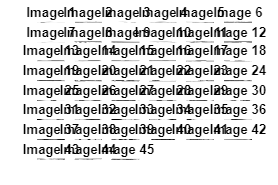

n = 28;
m = 28;

% Assuming outlier is a 784x65 matrix
% Update this line based on your variable name and dimensions

% Calculate the number of images
num_images = size(outlier, 2);

% Set up the figure with a larger size
figure('Position', [100, 100, 1200, 800]);

% Define the number of rows and columns in the subplot grid
num_rows = 8; % Adjust based on your preference
num_cols = ceil(num_images / num_rows);

% Loop through each column in outlier and display the images
for i = 1:num_images
    % Reshape the column vector back to a 28x28 matrix
    img_matrix = reshape(outlier(:, i), n, m);

    % Add a subplot
    subplot(num_rows, num_cols, i);

    % Display the image
    imagesc(img_matrix);
    colormap gray;
    axis off;
    title(['Image ', num2str(i)]);
end

n = 224;
m = 224;

% Assuming outlier is a 784x65 matrix
% Update this line based on your variable name and dimensions

% Calculate the number of images
num_images = size(outlier_org, 2)

num_images = 45

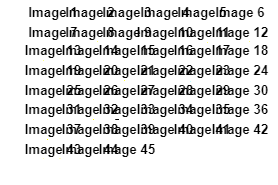


% Set up the figure with a larger size
%figure('Position', [100, 100, 1200, 800]);

% Define the number of rows and columns in the subplot grid
num_rows = 8; % Adjust based on your preference
num_cols = ceil(num_images / num_rows);

% Loop through each column in outlier_org and display the images
for i = 1:num_images
    % Reshape the column vector back to a 28x28 matrix
    img_matrix = reshape(outlier_org(:, i), 224, 224,3);

    % Add a subplot
    subplot(num_rows, num_cols, i);

    % Display the image
    imagesc(img_matrix);
    %imshow(image_matrix)
    colormap gray;
    axis off;
    title(['Image ', num2str(i)]);
end

fileStruct=image_files(ind_O_1,1)

fileStruct = 45×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


for i = 1:length(fileStruct)
    % Extract the file name from the struct
    fileNames{i} = fileStruct(i).name;
end

% Convert the cell array to a regular character vector if needed
fileNamesVector = char(fileNames);

% Display or use the file names as needed
disp(fileNamesVector);

B001.jpg     
B012.jpg     
B015.jpg     
B017.jpg     
B024.jpg     
B037.jpg     
B040.jpg     
B045.jpg     
B048.jpg     
B062.jpg     
B065.jpg     
B072.jpg     
B076.jpg     
B081.jpg     
B084.jpg     
B087.jpg     
B099.jpg     
B105.jpg     
B115.jpg     
B118.jpg     
G0103.jpg    
G021.jpg     
G026.jpg     
G048.jpg     
G061.jpg     
G067.jpg     
G079.jpg     
G080.jpg     
G088.jpg     
G091.jpg     
GR127.jpg    
GR20.jpg     
GR65.jpg     
GR98.jpg     
MexHrls01.jpg
MexHrls04.jpg
MexHrls09.jpg
MexHrls11.jpg
MexHrls14.jpg
MexHrls16.jpg
Pek004.jpg   
Pek005.jpg   
Pek010.jpg   
Pek011.jpg   
Pek013.jpg   
MexHrls01.jpg
MexHrls04.jpg
MexHrls09.jpg
MexHrls11.jpg
MexHrls14.jpg
MexHrls16.jpg
Pek004.jpg   
Pek005.jpg   
Pek010.jpg   
Pek011.jpg   
Pek013.jpg   


sourceFolder = fileStruct.folder

sourceFolder = 'C:\Users\shukl\Documents\GitHub\DogBreed\train\Dog'

cd (sourceFolder)
% Specify the destination folder where you want to copy the images
destinationFolder = 'Dog_out';
mkdir (destinationFolder)

% Names of the images you want to copy (replace with your actual vector)
imageNamesToCopy = (fileNamesVector)

imageNamesToCopy = 56×13 char array
    'B001.jpg     '
    'B012.jpg     '
    'B015.jpg     '
    'B017.jpg     '
    'B024.jpg     '
    'B037.jpg     '
    'B040.jpg     '
    'B045.jpg     '
    'B048.jpg     '
    'B062.jpg     '
    'B065.jpg     '
    'B072.jpg     '
    'B076.jpg     '
    'B081.jpg     '
    'B084.jpg     '
    'B087.jpg     '
    'B099.jpg     '
    'B105.jpg     '
    'B115.jpg     '
    'B118.jpg     '
    'G0103.jpg    '
    'G021.jpg     '
    'G026.jpg     '
    'G048.jpg     '
    'G061.jpg     '
    'G067.jpg     '
    'G079.jpg     '
    'G080.jpg     '
    'G088.jpg     '
    'G091.jpg     '
    'GR127.jpg    '
    'GR20.jpg     '
    'GR65.jpg     '
    'GR98.jpg     '
    'MexHrls01.jpg'
    'MexHrls04.jpg'
    'MexHrls09.jpg'
    'MexHrls11.jpg'
    'MexHrls14.jpg'
    'MexHrls16.jpg'
    'Pek004.jpg   '
    'Pek005.jpg   '
    'Pek010.jpg   '
    'Pek011.jpg   '
    'Pek013.jpg   '
    'MexHrls01.jpg'
    'MexHrls04.jpg'
    'MexHrls09.jpg'
    


% Loop through each image name in the vector
for i = 1:length(imageNamesToCopy)
    % Construct the full file path for the source image
    sourceImagePath = fullfile(sourceFolder, imageNamesToCopy(i));
    
    % Check if the source image exists
    if exist(sourceImagePath, 'file')
        % Construct the full file path for the destination image
        destinationImagePath = fullfile(destinationFolder, imageNamesToCopy(i));
        
        % Copy the image from source to destination
        copyfile(sourceImagePath, destinationImagePath);
        
        % Display a message indicating the copy operation
        disp(['Copied: ', imageNamesToCopy(i)]);
    else
        % Display a message if the source image does not exist
        disp(['Image not found: ', imageNamesToCopy(i)]);
    end
end

Image not found: B
Image not found: B
Image not found: B
Image not found: B
Image not found: B
Image not found: B
Image not found: B
Image not found: B
Image not found: B
Image not found: B
Image not found: B
Image not found: B
Image not found: B
Image not found: B
Image not found: B
Image not found: B
Image not found: B
Image not found: B
Image not found: B
Image not found: B
Image not found: G
Image not found: G
Image not found: G
Image not found: G
Image not found: G
Image not found: G
Image not found: G
Image not found: G
Image not found: G
Image not found: G
Image not found: G
Image not found: G
Image not found: G
Image not found: G
Image not found: M
Image not found: M
Image not found: M
Image not found: M
Image not found: M
Image not found: M
Image not found: P
Image not found: P
Image not found: P
Image not found: P
Image not found: P
Image not found: M
Image not found: M
Image not found: M
Image not found: M
Image not found: M
Image not found: M
Image not found: P
Image not fo